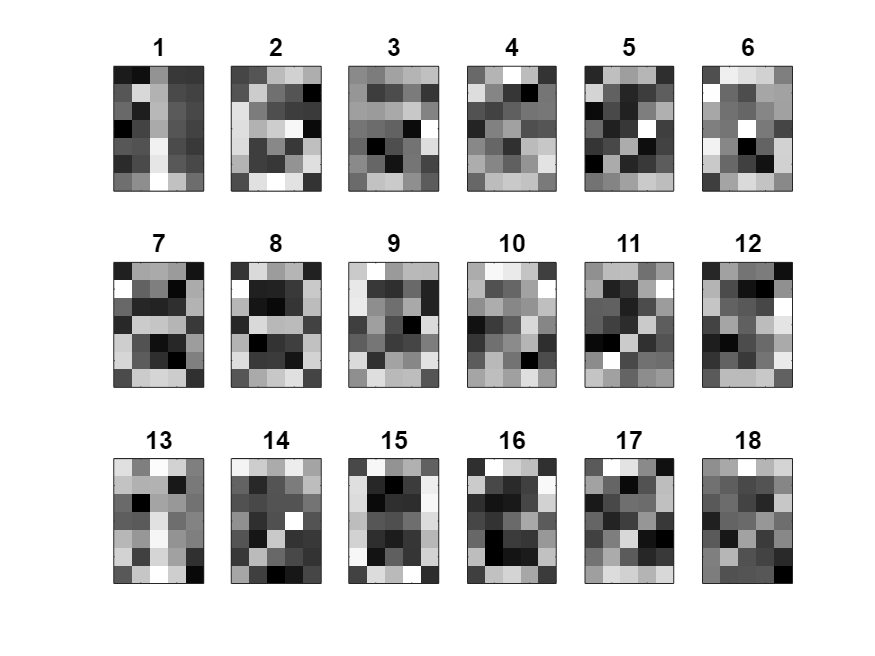

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1. Dataset generation and visualization
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
seed=1234; number=18; target=[8]; freq=0.5;
[Xtr,ytr]=uo_nn_dataset(seed,number,target,freq); % Training
uo_nn_Xyplot(Xtr,ytr)
seed=5678; freq=0.0;
[Xte,yte]=uo_nn_dataset(seed,number,target,freq);  % Test
uo_nn_Xyplot(Xte,yte)

% only the first 10 pixels retained becasue of uosol maxsize limitations.
Xtr = Xtr(1:10,:), ytr,

Xtr =   -11.2117    8.5784   -8.2363  -11.4127  -31.3497   -9.9915  -10.0134   -9.8603   -5.8843   -5.6767   -5.9169   -5.4280   12.1599  -14.1386   -8.1887   11.5315  -15.7276   -7.7358
   10.8639    6.6966   46.1249   11.9861    2.8732   12.0420    8.8078    6.9858   -4.5738    6.4063    8.0916    6.2225    5.9912   17.9804   12.1400   12.5406   18.3571   12.6479
    4.8611   21.9754   15.0901    9.6655   11.6102    7.1156   17.6479   14.5913    9.2044   -1.3036   10.7726    2.0283   16.2538   12.0831   10.4842   15.1048   -6.1564    9.4462
    8.4874    6.2533   13.6022   16.2449   28.0653    6.5117   16.5046   11.1553  -10.3503    7.8259   13.6197    1.5306   19.9293    1.8370    4.1173   10.9555   19.0754    9.6224
   -2.2999   -6.6975  -10.9678  -12.0023  -11.2273  -14.6267  -14.4396  -18.0043   -6.9991  -10.0238  -10.5468   -7.2992   -0.9618   -2.8015  -10.1836   18.9589   -7.8968   -9.3524
   10.4784   10.0072   11.1202    8.6785   19.5467    9.7578    3.3498   11.7214  -13.198

ytr =      1     1     0     1     0     1     1     1     0     0     1     1     0     1     1     0     0     1


Xte = Xte(1:10,:), yte

Xte =   -14.8230   -9.6199    1.8254   -8.1005  -14.8719  -12.4014  -13.0453   -9.1045   12.1726    4.4915    2.2298  -16.7793   16.2842   24.6879   -8.2954  -10.7391   -7.9898    3.2795
  -16.4717   -7.5928   -1.2410    9.3598   14.0395   17.8973    6.4456   11.5127   22.1758   18.3560   11.7680    8.4549   -5.9347   16.4867   13.8741   16.5536   20.6633    8.4839
    1.5131    6.2726    7.0401   27.1025    7.7676   14.8080    7.0630    3.7570    3.1977   15.8360   12.2979   -0.8919   22.8623    9.1271    1.2556   10.6218   15.6627   26.4552
  -10.8555    9.3576   11.0870   11.2871   12.3294   12.1386    4.9205    6.9471    9.0223    8.8645   -4.7537    0.7283   13.0399   23.2802    5.0356    8.1806    0.2311   11.0569
  -11.0521    4.5915   13.9121  -20.8850  -13.5870   -3.3149  -14.9431  -11.5565    8.6858  -15.5951    5.0209  -21.8223   -5.9021    7.7577   -5.2183  -10.4984  -20.8806   17.5218
   -6.7751   -7.6882    4.5318   18.9843   17.9736   20.6820   19.4800   16.2273   17.869

yte =      0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0


n=size(Xtr,1);
%%%%%%%%%%%%%%%%%%%%%%%
% 2. Problem definition
%%%%%%%%%%%%%%%%%%%%%%%
%    Auxiliary functions
sig = @(X)          1./(1+exp(-X));
y   = @(X,w)        sig(w'*sig(X));
acc = @(Xds,yds,wo) 100*sum(yds==round(y(Xds,wo)))/size(Xds,2);
%    Problem and initial iterate.
la = 1;
P.f  = @(w) (norm(y(Xtr,w)-ytr)^2)/size(ytr,2) + (la*norm(w)^2)/2;
P.g  = @(w) (2*sig(Xtr)*((y(Xtr,w)-ytr).*y(Xtr,w).*(1-y(Xtr,w)))')/size(ytr,2)+la*w;
w1 = zeros(n,1);
%    Optimization parameters
par.iAC = 4; % uosolNW32 linesearch.
par.isd = 3; % QNM
%    Training (...sorry, I ment "optimization"... :-)
[sol,par,opt] = uosol(P,w1,par);

uosol is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\micha\OneDrive\Desktop\OTDM\uolib

Change the MATLAB current folder or add its folder to the MATLAB path.

wo = opt.xo     % optimal solution
%%%%%%%%%%%%%%%%%%%%%%%
% 3. Accuracies
%%%%%%%%%%%%%%%%%%%%%%%
acc(Xtr,ytr,wo)  % Traning accuracy
acc(Xte,yte,wo)  % Test accuracy